Hour 01: 634 target bins, 691 reference bins


Hour 01: 402 / 634 bins significant


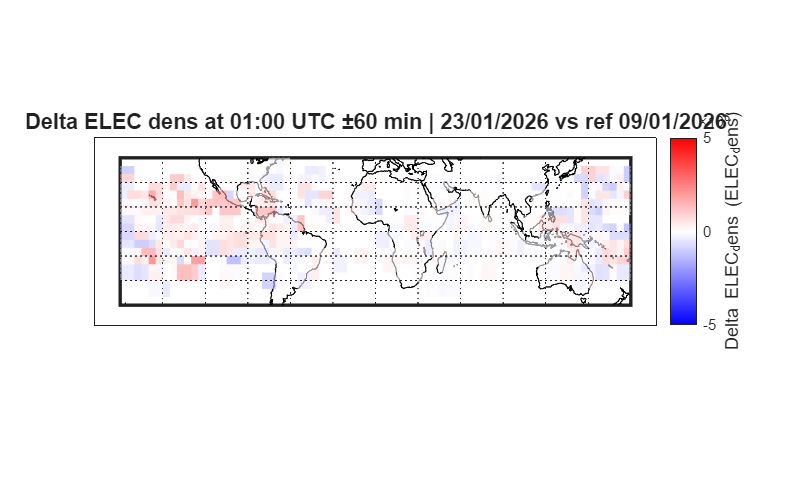

Hour 03: 654 target bins, 494 reference bins


Hour 03: 289 / 654 bins significant


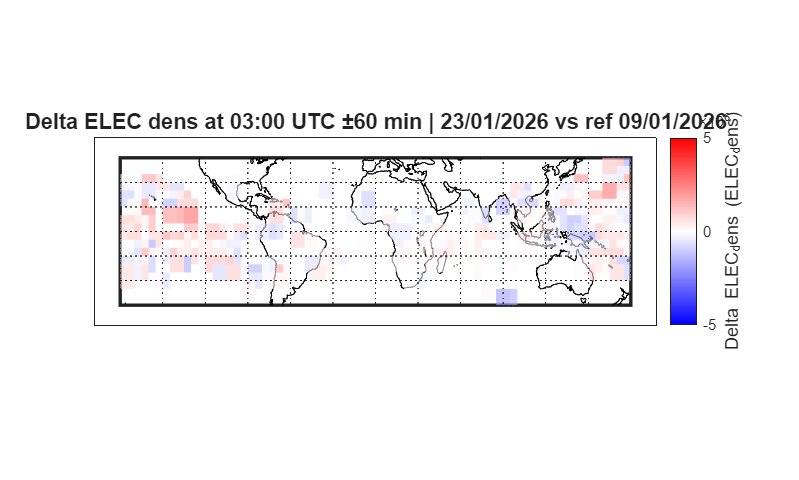

Hour 05: 649 target bins, 655 reference bins


Hour 05: 395 / 649 bins significant


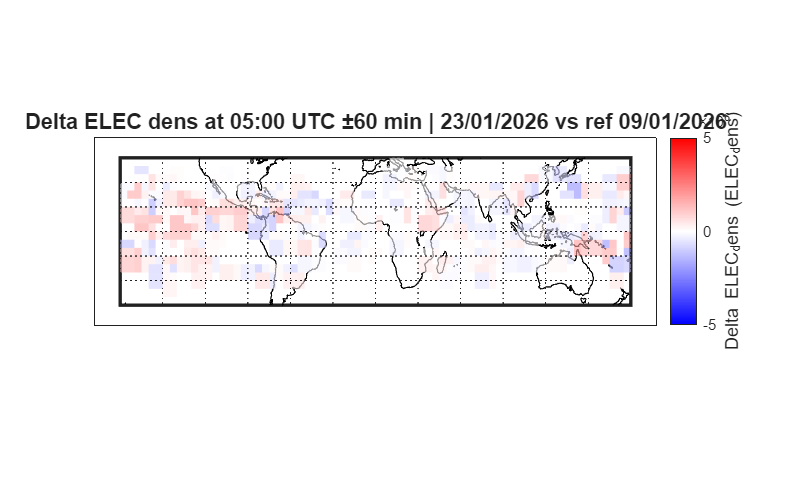

Hour 07: 745 target bins, 679 reference bins


Hour 07: 460 / 745 bins significant


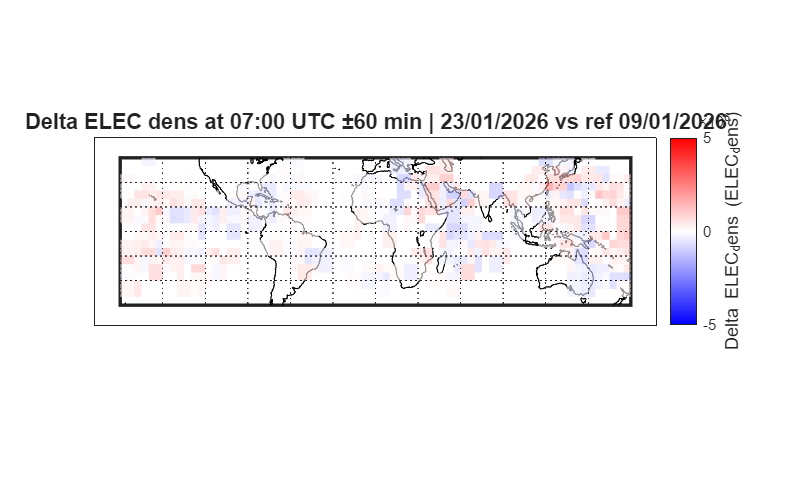

Hour 09: 710 target bins, 656 reference bins


Hour 09: 442 / 710 bins significant


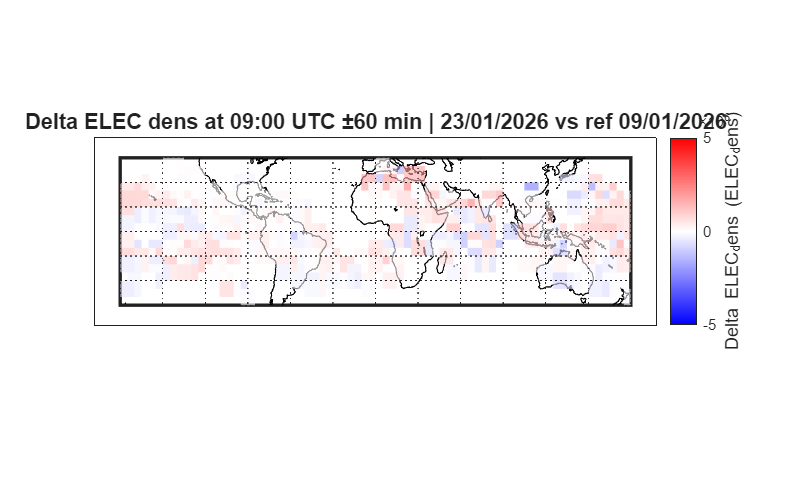

Hour 11: 597 target bins, 613 reference bins


Hour 11: 348 / 597 bins significant


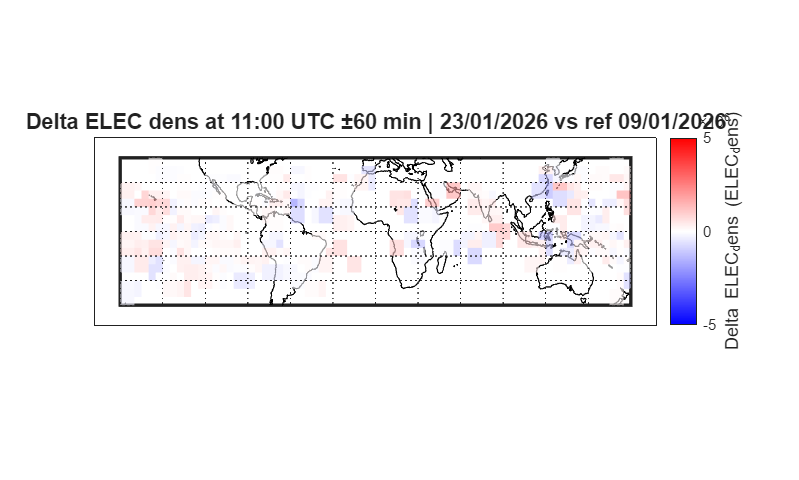

Hour 13: 500 target bins, 558 reference bins


Hour 13: 266 / 500 bins significant


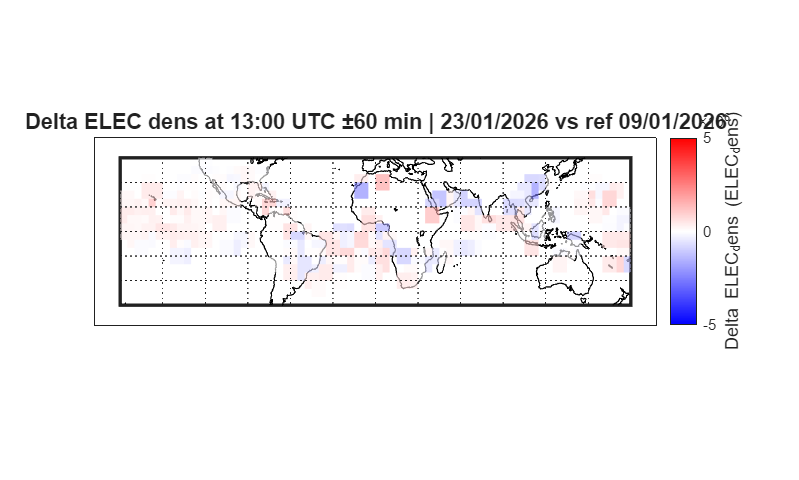

Hour 15: 503 target bins, 597 reference bins


Hour 15: 302 / 503 bins significant


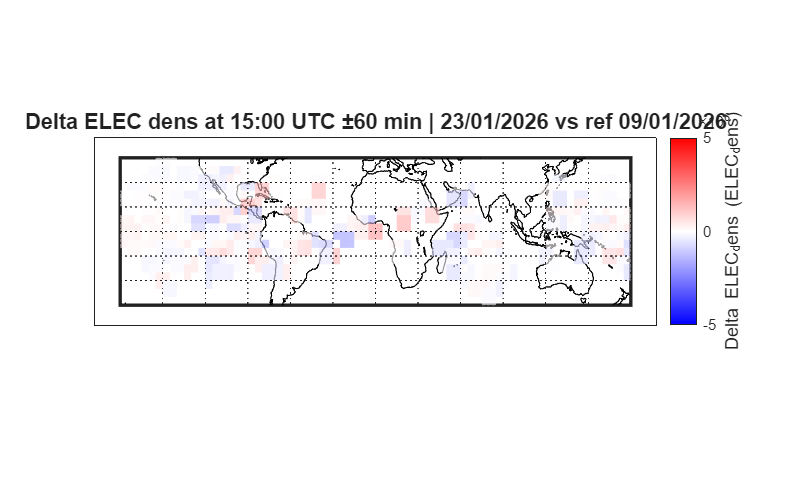

Hour 17: 698 target bins, 687 reference bins


Hour 17: 470 / 698 bins significant


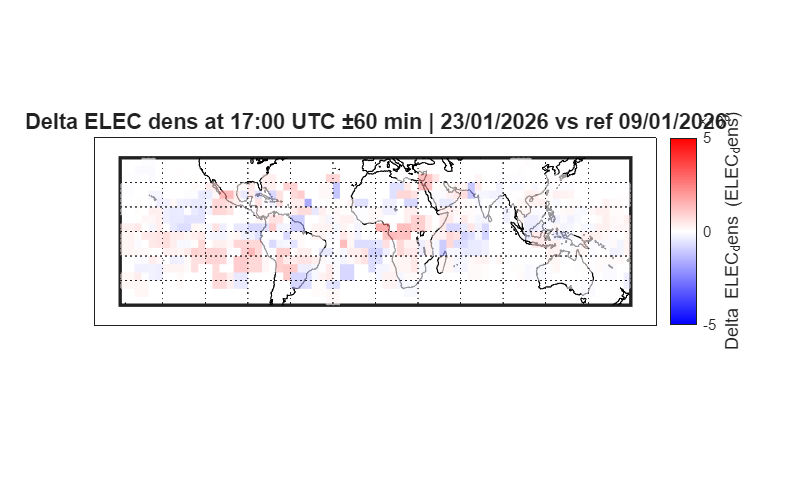

Hour 19: 731 target bins, 722 reference bins


Hour 19: 482 / 731 bins significant


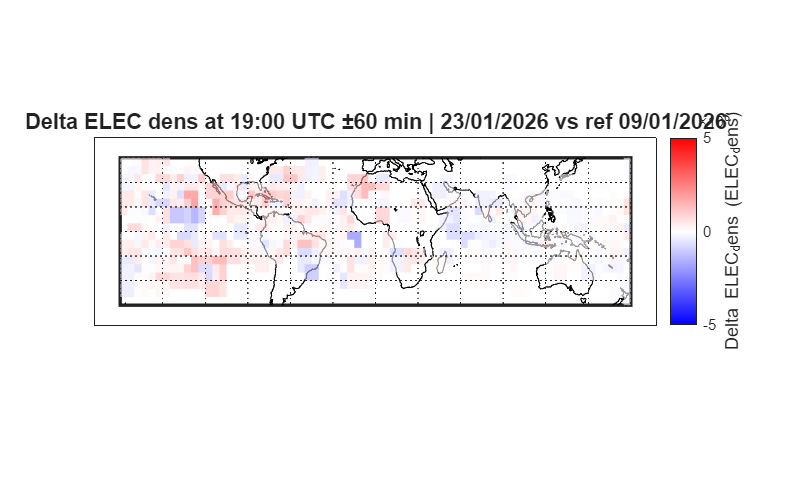

Hour 21: 772 target bins, 626 reference bins


Hour 21: 445 / 772 bins significant


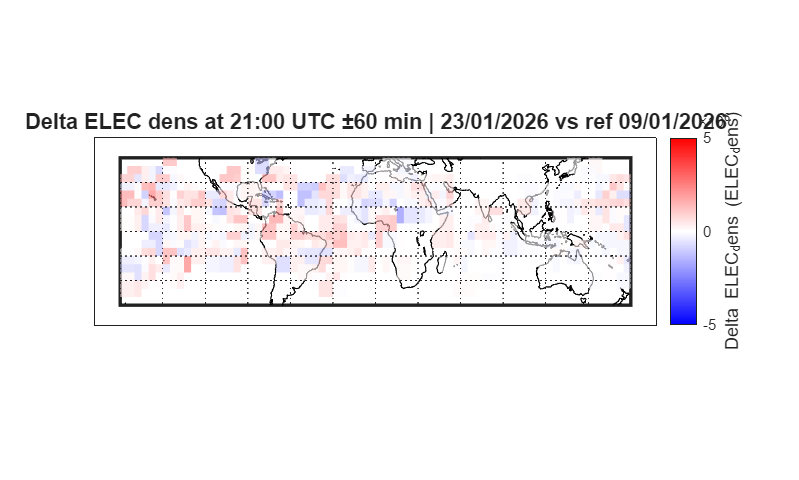

Hour 23: 753 target bins, 617 reference bins


Hour 23: 435 / 753 bins significant


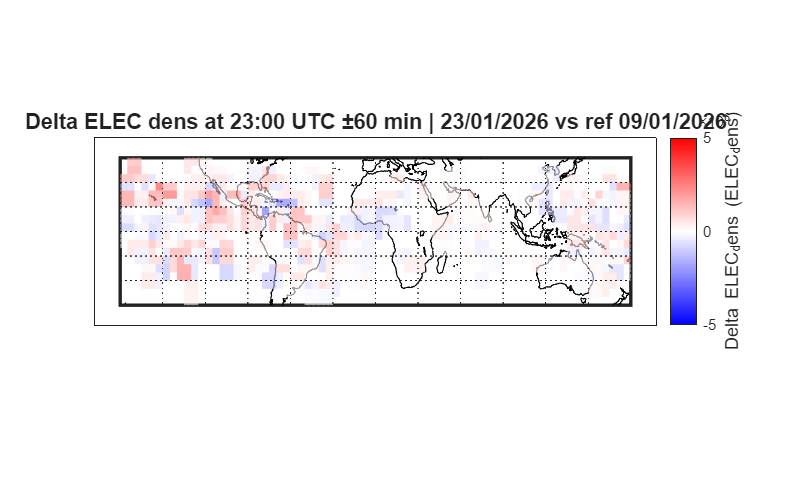

%% COSMIC delta ELEC_dens heatmap
clear min
reference_date = [COSMIC_data_reference{100}.day, COSMIC_data_reference{100}.month, year];
current_date   = [COSMIC_data{100}.day,           COSMIC_data{100}.month,           year];

%USER PARAMETERS
filter_quartiles = false;
lower_pct        = 25;
upper_pct        = 75;
bin_size         = 5;  
delta_threshold  = 0;   

%HOUR LOOP
for target_hour = 1:2:23
    target_minute  = 00;
    time_tolerance = 60;

    all_lat     = [];
    all_lon     = [];
    all_ELEC_dens     = [];
    ref_all_lat = [];
    ref_all_lon = [];
    ref_all_ELEC_dens = [];

    %Collect target data
    for i = 1:length(COSMIC_data)
        file_total_minutes   = COSMIC_data{i}.hour * 60 + COSMIC_data{i}.minute;
        target_total_minutes = target_hour * 60 + target_minute;
        if abs(file_total_minutes - target_total_minutes) > time_tolerance, continue; end

        lat = COSMIC_data{i}.GEO_lat;
        lon = COSMIC_data{i}.GEO_lon;
        ELEC_dens = COSMIC_data{i}.ELEC_dens;

        if isempty(lat) || isempty(lon) || isempty(ELEC_dens), continue; end
        if any(isnan(lat)) || any(isnan(lon)) || any(isnan(ELEC_dens)), continue; end

        all_lat = [all_lat; lat];
        all_lon = [all_lon; lon];
        all_ELEC_dens = [all_ELEC_dens; ELEC_dens];
    end

    %Collect reference data
    for i = 1:length(COSMIC_data_reference)
        file_total_minutes   = COSMIC_data_reference{i}.hour * 60 + COSMIC_data_reference{i}.minute;
        target_total_minutes = target_hour * 60 + target_minute;
        if abs(file_total_minutes - target_total_minutes) > time_tolerance, continue; end

        lat = COSMIC_data_reference{i}.GEO_lat;
        lon = COSMIC_data_reference{i}.GEO_lon;
        ELEC_dens = COSMIC_data_reference{i}.ELEC_dens;

        if isempty(lat) || isempty(lon) || isempty(ELEC_dens), continue; end
        if any(isnan(lat)) || any(isnan(lon)) || any(isnan(ELEC_dens)), continue; end

        ref_all_lat = [ref_all_lat; lat];
        ref_all_lon = [ref_all_lon; lon];
        ref_all_ELEC_dens = [ref_all_ELEC_dens; ELEC_dens];
    end

    if isempty(all_lat) || isempty(ref_all_lat)
        warning('No points found for hour %02d.', target_hour);
        continue
    end

    %Quartile filter
    if filter_quartiles
        q_low  = prctile(all_ELEC_dens, lower_pct);
        q_high = prctile(all_ELEC_dens, upper_pct);
        keep   = all_ELEC_dens >= q_low & all_ELEC_dens <= q_high;
        all_lat = all_lat(keep);
        all_lon = all_lon(keep);
        all_ELEC_dens = all_ELEC_dens(keep);
        fprintf('Hour %02d: kept %d / %d points (%.0f-%.0f pctile)\n', ...
            target_hour, sum(keep), length(keep), lower_pct, upper_pct);
    end

    if isempty(all_lat)
        warning('No points remain after quartile filter for hour %02d.', target_hour);
        continue
    end

    %Bin target data
    bin_lat_idx = floor(all_lat / bin_size) * bin_size + bin_size/2;
    bin_lon_idx = floor(all_lon / bin_size) * bin_size + bin_size/2;
    valid = ~isnan(bin_lat_idx) & ~isnan(bin_lon_idx) & ...
            all_lat >= -90 & all_lat <= 90 & all_lon >= -180 & all_lon <= 180;
    [G, bin_lat, bin_lon] = findgroups(bin_lat_idx(valid), bin_lon_idx(valid));
    bin_ELEC_dens = splitapply(@max, all_ELEC_dens(valid), G);

    %Bin reference data
    ref_bin_lat_idx = floor(ref_all_lat / bin_size) * bin_size + bin_size/2;
    ref_bin_lon_idx = floor(ref_all_lon / bin_size) * bin_size + bin_size/2;
    ref_valid = ~isnan(ref_bin_lat_idx) & ~isnan(ref_bin_lon_idx) & ...
                ref_all_lat >= -90 & ref_all_lat <= 90 & ref_all_lon >= -180 & ref_all_lon <= 180;
    [G_ref, ref_bin_lat, ref_bin_lon] = findgroups(ref_bin_lat_idx(ref_valid), ref_bin_lon_idx(ref_valid));
    ref_bin_ELEC_dens = splitapply(@max, ref_all_ELEC_dens(ref_valid), G_ref);

    fprintf('Hour %02d: %d target bins, %d reference bins\n', ...
        target_hour, length(bin_ELEC_dens), length(ref_bin_ELEC_dens));

    %Match bins and compute delta ELEC_dens
    tol = bin_size * 0.01;
    n_bins    = length(bin_lat);
    delta_ELEC_dens = nan(n_bins, 1);

    for b = 1:n_bins
        match = abs(ref_bin_lat - bin_lat(b)) < tol & ...
                abs(ref_bin_lon - bin_lon(b)) < tol;
        if any(match)
            delta_ELEC_dens(b) = bin_ELEC_dens(b) - ref_bin_ELEC_dens(match);
        end
    end

    %Apply threshold filter
    significant = ~isnan(delta_ELEC_dens) & abs(delta_ELEC_dens) > delta_threshold;
    plot_lat  = bin_lat(significant);
    plot_lon  = bin_lon(significant);
    cdata     = delta_ELEC_dens(significant);

    fprintf('Hour %02d: %d / %d bins significant\n', target_hour, sum(significant), n_bins);

    if isempty(plot_lat)
        fprintf('Hour %02d: nothing to plot.\n', target_hour);
        continue
    end

    %Build 2D grid nearest neighbour
    lat_vec = (-45 : bin_size : 45)';
    lon_vec = (-180 : bin_size : 180)';
    [LatGrid, LonGrid] = ndgrid(lat_vec, lon_vec);
    DeltaELEC_densGrid = nan(size(LatGrid));

    for r = 1:size(LatGrid, 1)
        for c = 1:size(LatGrid, 2)
            distances = (plot_lat - LatGrid(r,c)).^2 + (plot_lon - LonGrid(r,c)).^2;
            [d_min, idx_min] = min(distances);

            if sqrt(d_min) <= bin_size
                DeltaELEC_densGrid(r,c) = cdata(idx_min);
            end
        end
    end

    %Figure
    figure('Color', 'w', 'Position', [100 100 1000 600]);

    axesm('eqdcylin', ...
          'MapLatLimit', [-45  45], ...
          'MapLonLimit', [-180 180], ...
          'Frame', 'on', 'Grid', 'on')

    load coastlines
    geoshow(coastlat, coastlon, 'Color', 'k', 'LineWidth', 0.8)
    hold on

    % Heatmap
    h = pcolorm(LatGrid, LonGrid, DeltaELEC_densGrid);
    set(h, 'FaceAlpha', 0.6) 

    % Diverging red-white-blue colormap
    n = 256;
    r_ch = [linspace(1,1,n/2), linspace(1,0,n/2)]';
    g_ch = [linspace(0,1,n/2), linspace(1,0,n/2)]';
    b_ch = [linspace(0,1,n/2), linspace(1,1,n/2)]';
    colormap(flipud([r_ch g_ch b_ch]))

    clim([-5*10^6, 5*10^6])
    cb = colorbar;
    cb.Label.String   = 'Delta ELEC_dens (ELEC_dens)';
    cb.Label.FontSize = 11;

    title(sprintf('Delta ELEC dens at %02d:%02d UTC ±%d min | %02d/%02d/%04d vs ref %02d/%02d/%04d', ...
        target_hour, target_minute, time_tolerance, ...
        current_date(1),   current_date(2),   current_date(3), ...
        reference_date(1), reference_date(2), reference_date(3)), ...
        'FontSize', 13, 'FontWeight', 'bold')

    hold off
end